# 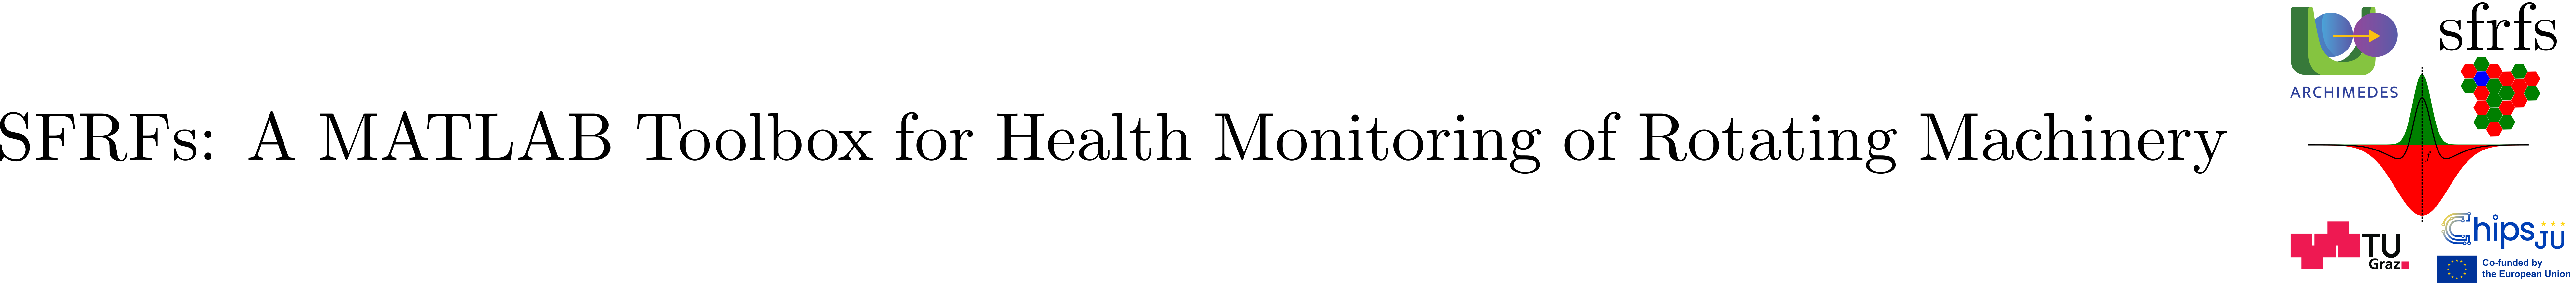

# **FFTEnsembleProcessor**

## Summary

Concrete subclass of `EnsembleProcessor` for parallel computation of FFTs on ensemble member signals.

Key features:

- Efficiently computes FFTs of temporal signal columns specified in the ensemble's configuration.

- Uses the ensemble's temporal snapshot columns and spectral suffix to automate input and output column naming.

- Supports parallel processing with configurable number of workers to speed up computation.

- Includes a static `compute` method performing the FFT on each temporal column and storing results in corresponding spectral columns.

- Designed as a lightweight, extensible spectral preprocessing step within the SFRFs toolbox.

- Constructor accepts number of workers and an `EnsembleBroker` instance managing ensemble metadata and files.

This class provides a foundational FFT processing step tailored for ensemble signal data with parallel execution support. It also serves as a reference implementation of concrete ensemble processor subclasses, demonstrating best practices for extending the abstract `EnsembleProcessor`.

## Description

`FFTEnsembleProcessor` inherits from [EnsembleProcessor](matlab:open('./EnsembleProcessor.mlx')) and provides a concrete implementation for computing FFTs on all temporal snapshot columns of ensemble members. The class uses the ensemble’s `temporalSnapshotColumns` to select input signals and automatically stores spectral results in new columns with names generated via `ensemble.mapToSpectralColumn()`. Processing is parallelized according to the configured number of workers.

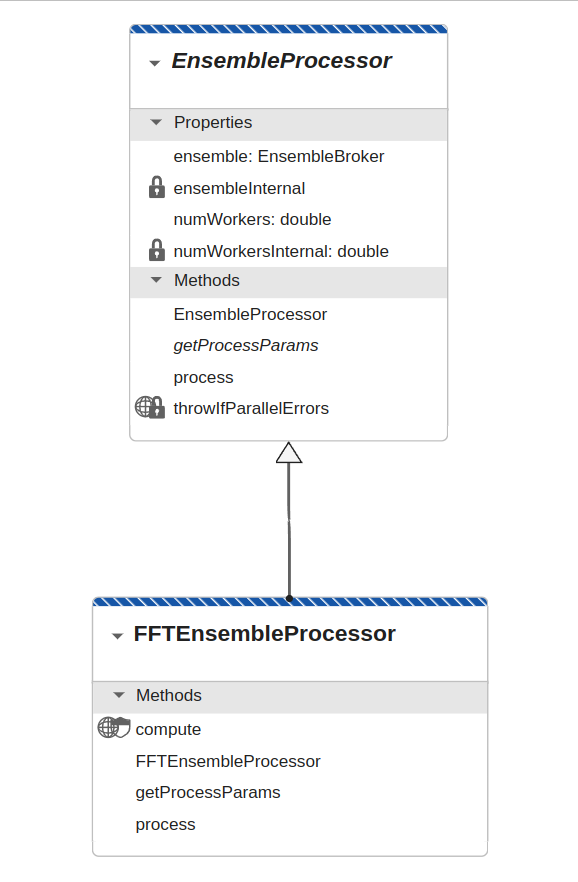

**Figure 1**. FFTEnsembleProcessor is a concrete subclass of EnsembleProcessor.

Figure 1 depicts the class diagram for this class. 

### Public properties

### Public methods

### Protected static methods

## Example

In the following example we compute the FFT on a mock ensemble with random samples. We don't pass an ensemble direclty to the processor but a broker instead. 

To illustrate the functionality using [EnsembleMock](matlab:open('../../../tests/EnsembleMock.m')) class, an auxiliary class for unit tests. See also [EnsembleBroker](matlab:open('./EnsembleBroker.mlx')).

### Mock ensemble

The **EnsembleMock** creates a temporary folder and saves ensemble files with random number of snapshots and random signals.

% Values from Wang et al.'s XJTU-SY datases.
% Create the snapshot parameters
sp = ParametersSnapshot(...
    'samplingFrequency', 25600, ...
    'duration', 1.28, ...
    'stride', 60);

% Define speeds and loads of the test
speeds = [35; 37.5; 40];
loads  = [12; 11; 10];

% Initialize and prepare EnsembleMock
ensembleMock = EnsembleMock( ...
    'numMembers', 7, ...
    'nSamples', sp.getTotalSamples(), ...
    'speeds', speeds, ...
    'loads', loads);

% Creates temp folder and saves ensemble files with random data
ensembleMock.prepare();   

% print entries for first member of mock ensemble
firstMember = read(ensembleMock.fileEnsembleDS);
head(firstMember);

    SnapshotIndex    HorizontalAcceleration    VerticalAcceleration    Speed    Load
    _____________    ______________________    ____________________    _____    ____

          1             {32768×1 double}         {32768×1 double}       35       12 
          2             {32768×1 double}         {32768×1 double}       35       12 
          3             {32768×1 double}         {32768×1 double}       35       12 
          4             {32768×1 double}         {32768×1 double}       35       12 
          5             {32768×1 double}         {32768×1 double}       35       12 



summary(firstMember);


firstMember: 5×5 table

Variables:

    SnapshotIndex: double
    HorizontalAcceleration: cell
    VerticalAcceleration: cell
    Speed: double
    Load: double

Statistics for applicable variables:

                              NumMissing     Min      Median     Max       Mean        Std    

    SnapshotIndex                 0            1         3         5         3        1.5811  
    HorizontalAcceleration        0                                                           
    VerticalAcceleration          0                                                           
    Speed                         0           35        35        35        35             0  
    Load                          

Our data store can be inspected as:

ensembleMock.fileEnsembleDS

ans =   fileEnsembleDatastore with properties:

                 ReadFcn: @EnsembleMock.readMember
        WriteToMemberFcn: @EnsembleMock.writeMember
           DataVariables: [2×1 string]
    IndependentVariables: "SnapshotIndex"
      ConditionVariables: [2×1 string]
       SelectedVariables: [5×1 string]
                ReadSize: 1
              NumMembers: 7
          LastMemberRead: "/tmp/tp276d4ae7_45db_48cd_a4f8_72856b33d9b4/member_001.mat"
                   Files: [7×1 string]


### Ensemble broker creation

We pass the mock ensemble to the broker constructor specifying the function handle to obtain the list of files and the names of the raw signal columns.

% Name of the columns containing the raw signals
temporalSnapshotColumns = {...
    'HorizontalAcceleration', 'VerticalAcceleration'};

% Create broker
broker = EnsembleBroker( ...
    'ensembleObject', ensembleMock.fileEnsembleDS, ...
    'getFilesFunction', @(obj) obj.Files, ...
    'temporalSnapshotColumns', temporalSnapshotColumns)

broker =   EnsembleBroker with properties:

                   ensemble: [1×1 fileEnsembleDatastore]
                  sortField: "SnapshotIndex"
         memberTableVarName: "ensembleMemberTable"
    temporalSnapshotColumns: {'HorizontalAcceleration'  'VerticalAcceleration'}
             spectralSuffix: "_FFT"


### Instantiating FFTEnsembleProcessor class

We create the instance of the processor allocating 5 workers. As can be seen from the code, all low level handling is automatically performed once the parameters of the computation are set in the broker class.

% Creation of the processor
processor = FFTEnsembleProcessor(...
    numWorkers = 5, ...
    ensemble = broker)

processor =   FFTEnsembleProcessor with properties:

    numWorkers: 5
      ensemble: [1×1 EnsembleBroker]


### Processing of the ensemble

Finally we compute the FFT of the signals.

% Parallel processing of the members
processor.process();

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 5 workers.


### Extracting the result

We obtain the first member from the [fileEnsembleDatastore](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html) handle.

% we recover first member of the ensemble in the broker
broker = processor.ensemble;
ensemble = broker.ensemble;
reset(ensemble);
ensemble

ensemble =   fileEnsembleDatastore with properties:

                 ReadFcn: @EnsembleMock.readMember
        WriteToMemberFcn: @EnsembleMock.writeMember
           DataVariables: [2×1 string]
    IndependentVariables: "SnapshotIndex"
      ConditionVariables: [2×1 string]
       SelectedVariables: [5×1 string]
                ReadSize: 1
              NumMembers: 7
          LastMemberRead: [0×0 string]
                   Files: [7×1 string]


firstMember = read(ensemble);
summary(firstMember);


firstMember: 5×5 table

Variables:

    SnapshotIndex: double
    HorizontalAcceleration: cell
    VerticalAcceleration: cell
    Speed: double
    Load: double

Statistics for applicable variables:

                              NumMissing     Min      Median     Max       Mean        Std    

    SnapshotIndex                 0            1         3         5         3        1.5811  
    HorizontalAcceleration        0                                                           
    VerticalAcceleration          0                                                           
    Speed                         0           35        35        35        35             0  
    Load                          

Note that the columns `HorizontalAcceleration_FFT`, and `VerticalAcceleration_FFT` appear not to have been added to the table. This is not the case, as we have added new columns to the table **we need to reconfigure** the variables in the [fileEnsembleDatastore](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html) handle.

### Reconfiguration of ensemble handle step by step

1. We first need to know what the new columns are, the broker has the necessary mappings:

FFTCols = string(...
    cellfun(@(c) broker.mapToSpectralColumn(c), ...
        temporalSnapshotColumns, ...
        'UniformOutput', false)).';
disp(FFTCols);

    "HorizontalAcceleration_FFT"
    "VerticalAcceleration_FFT"



This suffix is the default, but it can be changed when creating the broker, see [EnsembleBroker](matlab:open('./EnsembleBroker.mlx')) for further details.

2. The class [EnsembleDatastoreRegistry](matlab:open('./EnsembleDatastoreRegistry.mlx')) is designed to ease reconfiguration of the ensemble and persist this information in a registry, that way, we don't need to bookeep the changes ourselves. We add the ensemble to the registry first:

% Register the ensemble in the factory with a name
EnsembleDatastoreRegistry.addEnsemble(...
    name = "mock-ensemble", datastore = ensemble);

That will add the [fileEnsembleDatastore](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html) handle in a persistent registry.

3. We can now reconfigure the ensemble.

% Reconfigure the ensemble
ensemble = EnsembleDatastoreRegistry.reconfigureEnsemble( ...
    name = "mock-ensemble", ...
    DataVariables = [ensemble.DataVariables(:); FFTCols(:)], ...
    SelectedVariables = [ensemble.SelectedVariables;FFTCols(:)])

ensemble =   fileEnsembleDatastore with properties:

                 ReadFcn: @EnsembleMock.readMember
        WriteToMemberFcn: @EnsembleMock.writeMember
           DataVariables: [4×1 string]
    IndependentVariables: "SnapshotIndex"
      ConditionVariables: [2×1 string]
       SelectedVariables: [7×1 string]
                ReadSize: 1
              NumMembers: 7
          LastMemberRead: [0×0 string]
                   Files: [7×1 string]


4. Load and inspect a member as sanity check.

% Read a member
firstMember = read(ensemble);
summary(firstMember);


firstMember: 5×7 table

Variables:

    SnapshotIndex: double
    HorizontalAcceleration: cell
    VerticalAcceleration: cell
    HorizontalAcceleration_FFT: cell
    VerticalAcceleration_FFT: cell
    Speed: double
    Load: double

Statistics for applicable variables:

                                  NumMissing     Min      Median     Max       Mean        Std    

    SnapshotIndex                     0            1         3         5         3        1.5811  
    HorizontalAcceleration            0                                                           
    VerticalAcceleration              0                                                           
    HorizontalAcceleration_FFT

### Visualizing the spectra

We can extract the spectra of the first snapshot and visualize it.

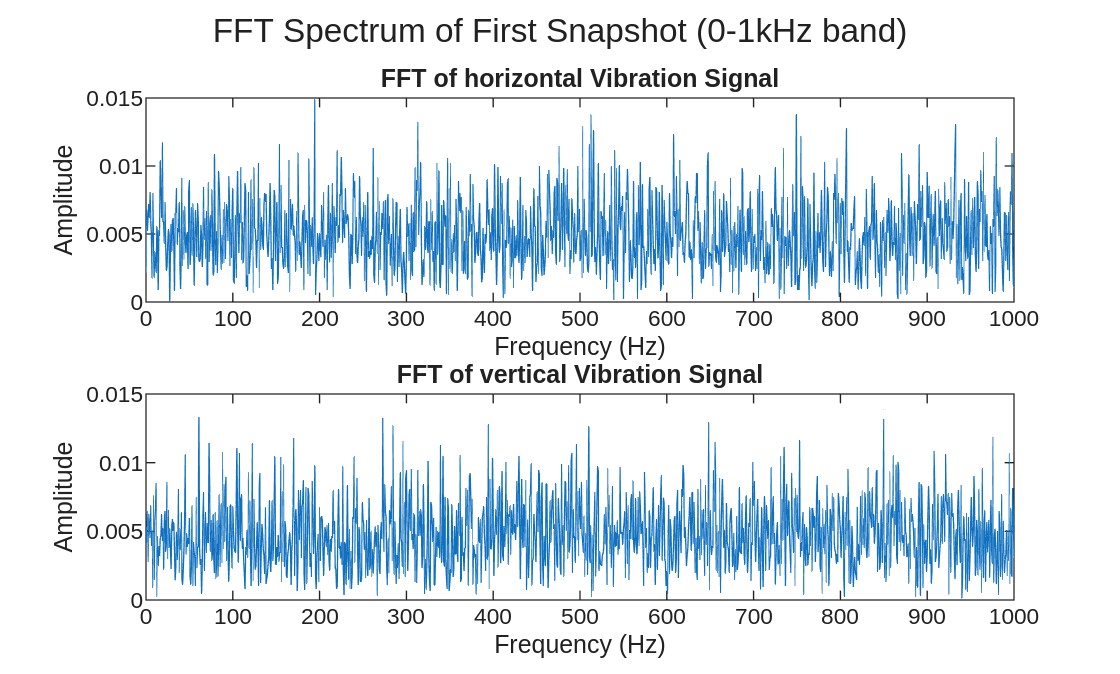

% Logical index for first snapshot
idx = firstMember.SnapshotIndex == 1;
% Extract horizontal acceleration
h_spec = firstMember.HorizontalAcceleration_FFT{idx};
v_spec = firstMember.VerticalAcceleration_FFT{idx};

h_spec = h_spec / length(h_spec);
v_spec = v_spec / length(v_spec);

plotSpectra(sp.getFrequencyDomain(),abs(h_spec),abs(v_spec),1000,...
    'FFT Spectrum of First Snapshot');

## API documentation

### MATLAB help

help FFTEnsembleProcessor

 FFTENSEMBLEPROCESSOR Parallel processor for computing FFTs of ensemble 
    signals.
 
    Efficiently computes and stores FFTs of temporal signal columns in 
    ensemble member tables. Uses the ensemble's configured temporal 
    snapshot  columns and spectral suffix to dynamically handle 
    input/output naming.
    Supports parallel processing with configurable worker count.
 
    Properties:
      numWorkers - Number of parallel workers (default: 2)
      ensemble   - EnsembleBroker instance managing file and metadata 
                   access
 
    Methods:
      FFTEnsembleProcessor(numWorkers, ensemble) - Constructor
      process(computeHandle)                     - Computes FFT on ensemble
 
    Notes:
      - The static method compute performs FFT on all temporal snapshot 
        columns using ensemble broker configuration.
      - Designed as a lightweight, extensible spectral preprocessing step.
 
    Example:
        ensembleStruct = struct('Files', {fileList});
     

### MATLAB documentation

doc FFTEnsembleProcessor

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

The source of the class is available in [FFTEnsembleProcessor](matlab:open('../../FFTEnsembleProcessor.m')).

## Test

Unit testing for the class is implemented in [TestFFTEnsembleProcessor](matlab:open('../../../tests/TestFFTEnsembleProcessor.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestFFTEnsembleProcessor');

Running TestFFTEnsembleProcessor
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 2 workers.
....
Done TestFFTEnsembleProcessor
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestFFTEnsembleProcessor/testProcessAddsFFTColumns                               | Passed
TestFFTEnsembleProcessor/testFFTValuesAreCorrect                                 | Passed
TestFFTEnsembleProcessor/testParallelProcessing                                  | Passed
TestFFTEnsembleProcessor/testNoFilesDoesNotError                                 | Passed



## Auxiliary functions

### Ploting horizontal and vertical spectra.

function fig = plotSpectra(freqAxis, h_spec, v_spec, nSamples, baseTitle)
% plotSpectra  Plot horizontal and vertical FFT spectra with band in title.
%
% Usage:
%   fig = plotSpectra(freqAxis, h_spec, v_spec, nSamples, baseTitle)
%
% Inputs:
%   freqAxis  - numeric vector of frequency values (Hz)
%   h_spec    - horizontal spectrum (complex or real magnitudes)
%   v_spec    - vertical spectrum (complex or real magnitudes)
%   nSamples  - upper frequency limit to display (scalar, Hz)
%   baseTitle - base title string (char or string). Optional.
%
% Output:
%   fig - figure handle

    arguments
        freqAxis (1,:) {mustBeNumeric}
        h_spec (1,:) {mustBeNumeric}
        v_spec (1,:) {mustBeNumeric}
        nSamples (1,1) {mustBeNumeric, mustBePositive}
        baseTitle (1,:) char = "FFT Spectrum"
    end
    
    % Validate that freqAxis length exactly matches both spectra
    lenF = numel(freqAxis);
    if lenF ~= numel(h_spec) || lenF ~= numel(v_spec)
        error('freqAxis must have the same length as h_spec and v_spec.');
    end
    
    % Build title with band info (display kHz when appropriate)
    if nSamples >= 1000
        bandStr = sprintf('0-%.0fkHz band', nSamples/1000);
    else
        bandStr = sprintf('0-%dHz band', nSamples);
    end
    fullTitle = sprintf('%s (%s)', string(baseTitle), bandStr);
    
    % Create figure and plots
    fig = figure;
    
    subplot(2,1,1);
    plot(freqAxis(1:length(h_spec)), abs(h_spec));
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    title('FFT of horizontal Vibration Signal');
    xlim([0, nSamples]);
    
    subplot(2,1,2);
    plot(freqAxis(1:length(v_spec)), abs(v_spec));
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    title('FFT of vertical Vibration Signal');
    xlim([0, nSamples]);
    
    sgtitle(fullTitle);

end

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).